# Applied Linear Systems Project

### Objective for this project is to design a state-feedback control system that can control the H-AUV depth and longitudinal position.

To do this, we must first develop LTI equations of motion.

#### Equations of Motion

The linearized external forces and moments are given by:


$$\begin{array}{l}
X_{\mathrm{ext}} \left(t\right)=\dot{\;\mathrm{mu}} \left(t\right)={-X}_{\dot{u} } \dot{u} \left(t\right)-X_u u\left(t\right)+X_T \left(t\right)\\
Z_{\mathrm{ext}} \left(t\right)=\;\dot{\mathrm{mw}} \left(t\right)=-Z_w \dot{w} \left(t\right)-Z_w w\left(t\right)-Z_{\dot{q} } \dot{q} \left(t\right)-Z_q q\left(t\right)+Z_s \left(t\right)+Z_b \left(t\right)\\
M_{\mathrm{ext}} \left(t\right)=I_y \dot{q} \left(t\right)=-M_{\dot{q} } \dot{q} \left(t\right)-M_q q\left(t\right)-M_{\dot{w} } \dot{w} \left(t\right)-M_w w\left(t\right)-x_s Z_s \left(t\right)-{x_b Z}_b \left(t\right)
\end{array}$$


In these equations, external control inputs are:

    $X_T$ is the thrust in the $x_o$- direction (N)

    $Z_s$  is the stern thrust in the $z_o$- direction (N)

    $Z_b$  is the bow thrust in the $z_o$- direction (N)

and:

    q is the pitch angle rate about the $y_o$ - axis (rad/s)

    u is the velocity in the $x_o$ -direction (m/s)

    w is the velocity in the $z$ -direction (m/s)

The linearized mapping between the AUV-fixed coordinates and the world coordinates are given by:


$$\begin{array}{l}
\dot{x} \left(t\right)=u\left(t\right)\\
\dot{z} \left(t\right)=w\left(t\right)\\
\theta^˙ \left(t\right)=q\left(t\right)
\end{array}$$


The **pitch angle θ, the depth z, and the position x** are directly measured with sensors to represent the **outputs of the model.**

With this given information, the solution to the problem is presented in the following  sections

**Problem 1: **Derive a complete state-space model for the AUV, including a state equation and an output equation.

In the given problem the outputs of the model are the derivatives of the control input. Hence, first we have to start by choosing proper state variables.


$$\begin{array}{l}
x\left(t\right)=y_1 \left(t\right),\dot{\;x} \left(t\right)=\dot{y_1 } \left(t\right)=u\left(t\right)\\
z\left(t\right)=y_2 \left(t\right),\dot{\;z} \left(t\right)=\dot{y_2 } \left(t\right)=w\left(t\right)\\
\theta \left(t\right)=y_3 \left(t\right),\theta^˙ \left(t\right)=\dot{y_3 } \left(t\right)=q\left(t\right)
\end{array}$$


Therefore from the above equations, we can determine that there are **six** state variables namely


$$y_1 \left(t\right),y_2 \left(t\right),y_3 \left(t\right),u\left(t\right),w\left(t\right),q\left(t\right)$$


Based on these state variables, now, we can start the derivation of complete state-space model for the AUV.

syms Udot(t) Wdot(t) Qdot(t) Y1dot(t) Y2dot(t) Y3dot(t) % States
syms U(t) W(t) Q(t) Y1(t) Y2(t) Y3(t) % state variables
syms X_udot X_u m Z_wdot Z_qdot Z_w Z_q M_wdot I_y M_qdot M_q M_w X_s X_b % Constants
syms XT(t) Zs(t) Zb(t) % Inputs
syms X(t) Theta(t) Z(t) % Output

k1 = m + Z_wdot;
k2 = I_y + M_qdot;

eqn_2_rhs = -(Z_w)*W(t) - Z_q*Q(t) + Zs(t) + Zb(t);
eqn_3_rhs = -(M_q)*Q(t) - M_w*W(t) - X_s*Zs(t) - X_b*Zb(t);
eqn_lhs = [k1, Z_qdot; M_wdot, k2];
eqn_rhs = [eqn_2_rhs; eqn_3_rhs];


Here, we can observe that equations of $\dot{w} \left(t\right)\;\mathrm{and}\;\dot{q} \left(t\right)$ contain derivatives of each others which is also known as 'algebraic loop'.

This problem can be solved with `linsolve` function from the symbolic toolbox of matlab which solve linear equations in matrix form.

output = linsolve(eqn_lhs, eqn_rhs);

Udot(t) = (-X_u*U(t) + XT(t))/(m + X_udot) % Equation 1

$$Udot(t) = \frac{\mathrm{XT}\left(t\right)-X_{u}\,U\left(t\right)}{X_{\mathrm{udot}}+m}$$

Wdot(t) = output(1,1)  % Equation 2

$$Wdot(t) = \frac{I_{y}\,\mathrm{Zb}\left(t\right)+I_{y}\,\mathrm{Zs}\left(t\right)+\ddddot{M}\,\mathrm{Zb}\left(t\right)+\ddddot{M}\,\mathrm{Zs}\left(t\right)-I_{y}\,Z_{q}\,Q\left(t\right)+M_{q}\,\ddddot{Z}\,Q\left(t\right)-\ddddot{M}\,Z_{q}\,Q\left(t\right)-I_{y}\,Z_{w}\,W\left(t\right)-\ddddot{M}\,Z_{w}\,W\left(t\right)+M_{w}\,\ddddot{Z}\,W\left(t\right)+X_{b}\,\ddddot{Z}\,\mathrm{Zb}\left(t\right)+X_{s}\,\ddddot{Z}\,\mathrm{Zs}\left(t\right)}{I_{y}\,Z_{\mathrm{wdot}}+\ddddot{M}\,Z_{\mathrm{wdot}}-M_{\mathrm{wdot}}\,\ddddot{Z}+I_{y}\,m+\ddddot{M}\,m}$$

Qdot(t) = output(2, 1) % Equation 3

$$Qdot(t) = -\frac{M_{\mathrm{wdot}}\,\mathrm{Zb}\left(t\right)+M_{\mathrm{wdot}}\,\mathrm{Zs}\left(t\right)+M_{q}\,Z_{\mathrm{wdot}}\,Q\left(t\right)-M_{\mathrm{wdot}}\,Z_{q}\,Q\left(t\right)+M_{w}\,Z_{\mathrm{wdot}}\,W\left(t\right)-M_{\mathrm{wdot}}\,Z_{w}\,W\left(t\right)+M_{q}\,m\,Q\left(t\right)+X_{b}\,Z_{\mathrm{wdot}}\,\mathrm{Zb}\left(t\right)+X_{s}\,Z_{\mathrm{wdot}}\,\mathrm{Zs}\left(t\right)+M_{w}\,m\,W\left(t\right)+X_{b}\,m\,\mathrm{Zb}\left(t\right)+X_{s}\,m\,\mathrm{Zs}\left(t\right)}{I_{y}\,Z_{\mathrm{wdot}}+\ddddot{M}\,Z_{\mathrm{wdot}}-M_{\mathrm{wdot}}\,\ddddot{Z}+I_{y}\,m+\ddddot{M}\,m}$$

**Problem 2.** Using the numerical values and formulas listed below, compute the following parameters at the top of your Matlab script.

From observing the output of the previous problem, we can determine A, B, C, and D.

% Variables declaration
m = 500; L = 25;
Z_q = 9.5e2; I_y = (1/300)*m*L^2;
M_qdot = (1/20)*I_y; M_q = 1.1e3;
X_udot = (1/30)*m; M_wdot = (1/40)*I_y;
X_u = 94; M_w = 320;
Z_wdot = (1/10)*m; X_s = -(1/3)*L;
Z_w = 4.7e2; X_b = (1/3)*L;
Z_qdot = (1/20)*m; U_max = 3e6;

den_udot = m + X_udot;
den_wdot = I_y*Z_wdot + M_qdot*Z_wdot - M_wdot*Z_qdot + I_y*m + M_qdot*m;
den_qdot = -(I_y*Z_wdot + M_qdot*Z_wdot - M_wdot*Z_qdot + I_y*m + M_qdot*m);
 
A_1_1 = -I_y*Z_w - M_qdot*Z_w + M_w*Z_qdot;
A_1_2 = -I_y*Z_q + M_q*Z_qdot - M_qdot*Z_q;
A_2_1 = M_w*Z_wdot - M_wdot*Z_w + M_w*m;
A_2_2 = M_q*Z_wdot - M_wdot*Z_q + M_q*m;

B_1_1 = 1;  %Xt
B_2_2 = I_y + M_qdot + X_b*Z_qdot; % Zb
B_2_3 = I_y + M_qdot + X_s*Z_qdot; % Zs
B_3_2 = M_wdot + X_b*Z_wdot + X_b*m; % Zb
B_3_3 = M_wdot + X_s*Z_wdot + X_s*m; % Zs

% A matrix
A = [-X_u/den_udot, 0, 0, 0, 0, 0;...
     0, A_1_1/den_wdot, A_1_2/den_wdot, 0 ,0, 0;...
     0, A_2_1/den_qdot, A_2_2/den_qdot, 0, 0, 0;...
     1, 0, 0, 0, 0, 0;...
     0, 1, 0, 0, 0, 0;...
     0, 0, 1, 0, 0, 0];
% B matrix
B = [B_1_1/den_udot, 0, 0;...
     0, B_2_2/den_wdot, B_2_3/den_wdot;...
     0, B_3_2/den_qdot, B_3_3/den_qdot;...
     0, 0, 0;...
     0, 0, 0;...
     0, 0, 0];
 
 % C matrix
 C = [0, 0, 0, 1, 0, 0;...
      0, 0, 0, 0, 1, 0;...
      0, 0, 0, 0, 0, 1];
  
% D matrix
D = zeros([3, 3]);

% Get the eigen values of Matrix A
eigen_values = eig(A)

eigen_values =          0
         0
   -1.5840
   -0.2238
         0
   -0.1819


**Problem 3.** Use the variables defined in Problem 2 to construct the A, B, C, and D matrices for your linear state-space model, then use these matrices to generate an LTI object called ol_sys.

ol_sys = ss(A, B, C, D);
set(ol_sys, 'StateName', {'posx', 'posz', 'pitch', 'velx', 'velz', 'pitch_rate'},...
            'InputName', {'thrust', 'stern', 'bow'},...
            'OutputName', {'posx', 'posz', 'pitch'})

ol_sys


ol_sys =
 
  A = 
                     posx        posz       pitch        velx        velz  pitch_rate
   posx           -0.1819           0           0           0           0           0
   posz                 0     -0.8422      -1.683           0           0           0
   pitch                0     -0.2725     -0.9656           0           0           0
   velx                 1           0           0           0           0           0
   velz                 0           1           0           0           0           0
   pitch_rate           0           0           1           0           0           0
 
  B = 
                  thrust      stern        bow
   posx         0.001935          0          0
   posz                0   0.002167   0.001473
   pitch               0  -0.007671   0.007584
   velx                0          0          0
   velz                0          0          0
   pitch_rate          0          0          0
 
  C = 
                posx        posz

**Problem 4. **Apply the MINREAL function in Matlab to your LTI object from Problem 3 to determine whether your state-space model is a minimum realization.

% Minimum Realization
min_realization_system = minreal(ol_sys)


min_realization_system =
 
  A = 
                     posx        posz       pitch        velx        velz  pitch_rate
   posx           -0.1819           0           0           0           0           0
   posz                 0     -0.8422      -1.683           0           0           0
   pitch                0     -0.2725     -0.9656           0           0           0
   velx                 1           0           0           0           0           0
   velz                 0           1           0           0           0           0
   pitch_rate           0           0           1           0           0           0
 
  B = 
                  thrust      stern        bow
   posx         0.001935          0          0
   posz                0   0.002167   0.001473
   pitch               0  -0.007671   0.007584
   velx                0          0          0
   velz                0          0          0
   pitch_rate          0          0          0
 
  C = 
                

`minreal(ol_sys) `eliminates uncontrollable or unobservable state in state-space models, or cancels pole-zero pairs in transfer functions or zero-pole-gain models. The output has minimal order and the same response characteristics as the original model `ol_sys`. 

We can observe from the output of the `minreal` that state-space model generated in **Problem 3** is already a minimal realization as there is no pole-zero cancellation in the output.

**Problem 5.** Show that the open-loop system is Completely Controllable using all of the control inputs. Determine (and clearly document) whether any subsets of control inputs results in a Completely Controllable system. Justify your results.

% Controllability check

length_of_A = length(A)

length_of_A = 6


% % All Inputs
controllability_matrix = ctrb(A, B);
rank_of_controllability_matrix = rank(controllability_matrix) % Full Rank matrix

rank_of_controllability_matrix = 6

% Xt
controllability_matrix_xt = ctrb(A, B(:, 1));
rank_with_xt = rank(controllability_matrix_xt)

rank_with_xt = 2

% Zs
controllability_matrix_zs = ctrb(A, B(:, 2));
rank_with_zs = rank(controllability_matrix_zs)

rank_with_zs = 3

% Zb
controllability_matrix_zb = ctrb(A, B(:, 3));
rank_with_zb = rank(controllability_matrix_zb)

rank_with_zb = 3

% Xt and Zs
controllability_matrix_xt_zs = ctrb(A, [B(:, 1) B(:, 2)]);
rank_with_xt_zs = rank(controllability_matrix_xt_zs)

rank_with_xt_zs = 5

% Zs and Zb
controllability_matrix_zs_zb = ctrb(A, [B(:, 2) B(:, 3)]);
rank_with_zb_zs = rank(controllability_matrix_zs_zb)

rank_with_zb_zs = 4

% Zb and Xt
controllability_matrix_xt_zb = ctrb(A, [B(:, 3) B(:, 1)]);
rank_with_xt_zb = rank(controllability_matrix_xt_zb)

rank_with_xt_zb = 5

To check the controllablility of the system, we use `ctrb` function in the matlab which returns the controllability matrix `c`.

And the controllability of a system is dependent on the rank of controllability matrix i.e.  if `c` is a full rank matrix then the system is controllable otherwise it is not.

This can be seen from the above execution as well. System is controllable if and only if we take all the three inputs. In rest of the cases, `c` always has lower rank.

**Problem 6. **Compute the open loop poles, the natural frequencies with units of Hz, and the damping ratios for each eigenvalue.

% Open loop poles, natural frequencies and damping ratio 
[Wn, zeta, ol_poles] = damp(ol_sys);
table(Wn, zeta, ol_poles)

ans = 6×3 table
      Wn       zeta    ol_poles
    _______    ____    ________

          0     -1            0
          0     -1            0
          0     -1            0
    0.18194      1     -0.18194
    0.22377      1     -0.22377
      1.584      1       -1.584


**Problem 7. **Define an initial condition vector using the following initial values:

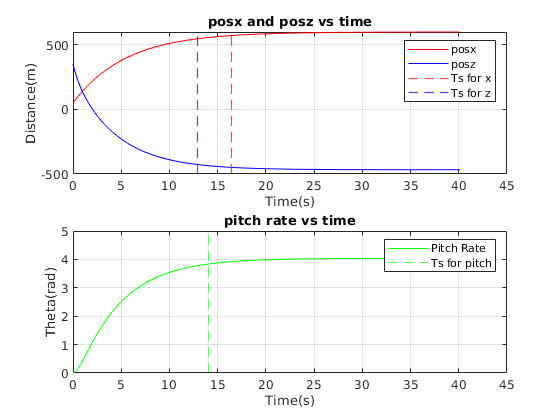

% Initial Condition Vector
U0 = 100; W0 = -300; Q0 = 0;
X0 = 50; Z0 = 350; Theta0 = deg2rad(45);
init_vector_states = [U0, W0, Q0, X0, Z0, Theta0];

% Inital value response of the open loop system
[y, t, x] = initial(ol_sys, init_vector_states);

% Get the properties of linear system and set the settling time to 5%
S = lsiminfo(y, t, 'SettlingTimeThreshold', 0.05);
S.SettlingTime;

figure
hold on
subplot(2, 1, 1);
plot(t, y(:, 1), 'r', t, y(:, 2), 'b'); 
grid on
xlabel("Time(s)"); ylabel("Distance(m)");
xline(S(1).SettlingTime, "--r", 'LineWidth', 1);
xline(S(2).SettlingTime, "--b", 'LineWidth', 1);
legend("posx", "posz", "Ts for x", "Ts for z");

title("posx and posz vs time");
hold off

subplot(2, 1, 2);
plot(t, deg2rad(y(:, 3)), 'g'); 
grid on
xlabel("Time(s)"); ylabel("Theta(rad)");  

xline(S(3).SettlingTime, '--g');
legend("Pitch Rate", "Ts for pitch"); 
title("pitch rate vs time");

**Problem 8**. Design a full-state feedback controller.

The list of desired poles for five design iteration is given below along with the comments.

1. With these poles, the control input crosses the limit of $U_{\mathrm{max}} =3\mathrm{e6}\left(N\right)$ and crashes into the wall of the tunnel.

% desired_poles = [-1, -2, -3+3j, -3-3j, -6, -3];

2. With these poles, the AUV's pitch angle oscillates around it origin and crashes into the wall near the tunnel

It also gives a slow response as the poles are near the origin

% desired_poles = [-1-1j, -1+1j, -3-3j , -3+3j, -2-2j, -2+2j];

3. To increase the speed of response, poles are placed far from the origin, but again the AUV crashes into the tunnel

% desired_poles = [-4 + 4j, -4-4j, -4.5, -3.57, -3.62, -4.25];

4. With these poles, AUV enters the tunnel but oscillates before coming to a hault.

The main reason behind this could be that, the poles are far away from the origin which increases the speed of response

but also increases the complexity of the control signal.

% desired_poles = [-2-2j, -2+2j, -6, -7, -8, -9]; % work but with oscillations

5. These poles give proper output i.e. AUV enters the tunnel without any oscillations which is shown in the animation as well

desired_poles = [-5-5j, -5+5j, -2.25, -2, -3, -3.25];  % Work properly

Matlab provides `place` function which calculates the gain matrix `G` for the desired closed loop poles of the system.

`place` function takes state matrices A and B, along with vectors of `desired_poles` as input.

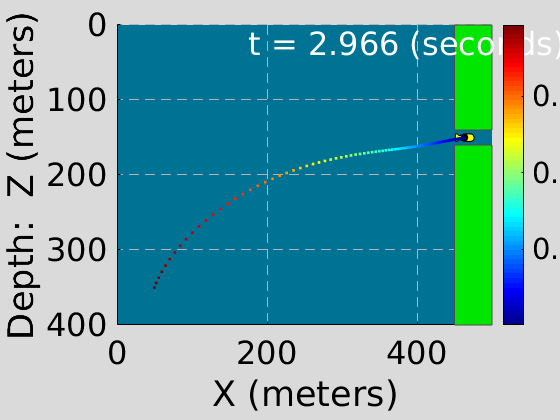

% % Gains for the desired the poles
G = place(A, B, desired_poles);

% Closed loop A matrix
Ac = (A-B*G);
 
cl_sys = ss(Ac, B, C, D);

% Initial Condition Vector
U0 = 100; W0 = -300; Q0 = 0;
X0 = 50-465; Z0 = 350-150; Theta0 = deg2rad(45);
init_vector_states = [U0, W0, Q0, X0, Z0, Theta0];

% Inital value response of the close loop system
[y, t, x] = initial(cl_sys, init_vector_states);
S = lsiminfo(y, t, 'SettlingTimeThreshold', 0.05);
S.SettlingTime;

% Coordinate Transformations
posx = y(:, 1)+465;
posz = y(:, 2)+150;
theta = deg2rad(y(:, 3));

animate_auv(t, posx, posz, theta, false)

**Final Design Plot**

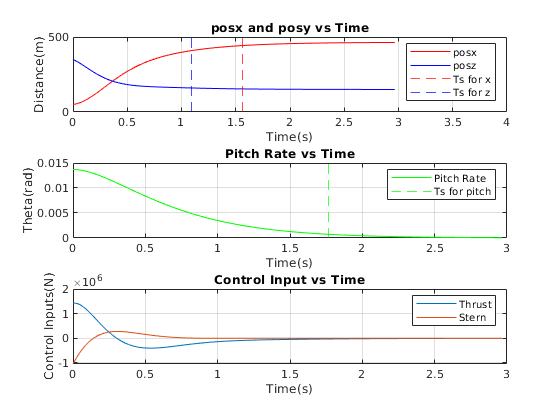

u = -G * x';

figure
hold on
subplot(3, 1, 1);
plot(t, y(:, 1)+465, 'r', t, y(:, 2)+150, 'b'); 
grid on
xlabel("Time(s)"); ylabel("Distance(m)"); 
axis([0 4 0 500]);
xline(S(1).SettlingTime, '--r');
xline(S(2).SettlingTime, '--b');
title("posx and posy vs Time");
legend("posx", "posz", "Ts for x", "Ts for z");
hold off

subplot(3, 1, 2);
plot(t, deg2rad(y(:, 3)), 'g'); 
grid on
xlabel("Time(s)"); ylabel("Theta(rad)"); 
xline(S(3).SettlingTime, '--g');
title("Pitch Rate vs Time");
legend("Pitch Rate", "Ts for pitch");
hold on

subplot(3, 1, 3);
plot(t, u(1, :), t, u(2, :)); 
grid on
xlabel("Time(s)"); ylabel("Control Inputs(N)");
title("Control Input vs Time");
legend("Thrust", "Stern");
hold off